# Lecture 3: Digital Image Fundamentals

# Part 4: Logical Operations

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in both Matlab IPT *imdata* folder and *images* folder in the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture3 - Digital Image Fundamentals

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

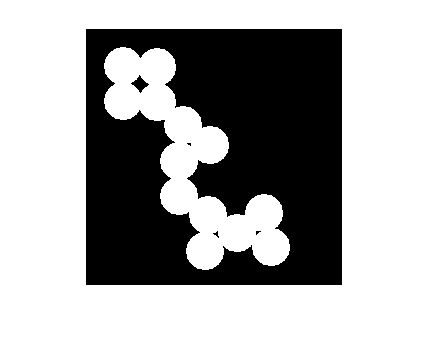

% read a binary image
I1 = imread('circles.png');
imshow(I1)

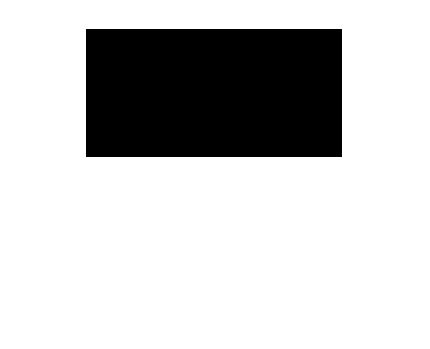

% create a binary image of the same size
I2 = ones(size(I1));
I2(1:128,:) = 0;
I2 = logical(I2); % convert to logical type to perform logical operations
imshow(I2)

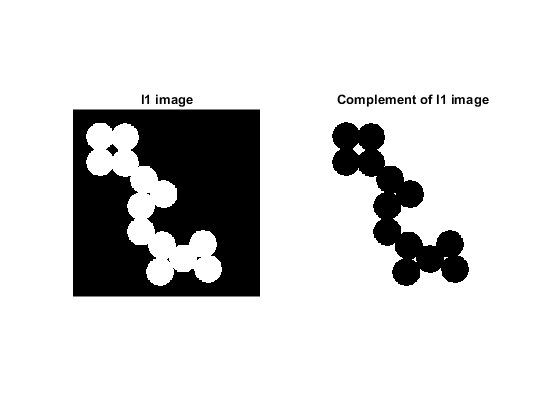

% perform logical operations on the images
figure, subplot(1,2,1), imshow(I1), title("I1 image")
subplot(1,2,2), imshow(not(I1)), title("Complement of I1 image")

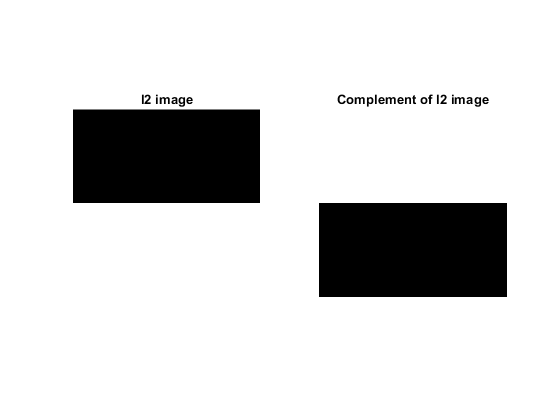

% you can use both ~ operator and not()
figure, subplot(1,2,1), imshow(I2), title("I2 image")
subplot(1,2,2), imshow(~I2), title("Complement of I2 image")

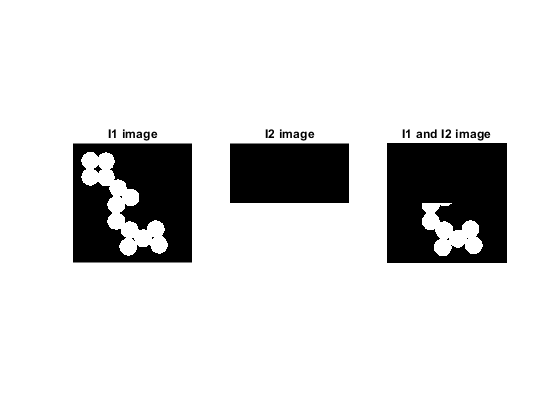

figure, subplot(1,3,1), imshow(I1), title("I1 image")
subplot(1,3,2), imshow(I2), title("I2 image")
subplot(1,3,3), imshow(and(I1,I2)), title("I1 and I2 image")

figure, subplot(1,3,1), imshow(I1), title("I1 image")
subplot(1,3,2), imshow(I2), title("I2 image")
subplot(1,3,3), imshow(I1&I2), title("I1 and I2 image")

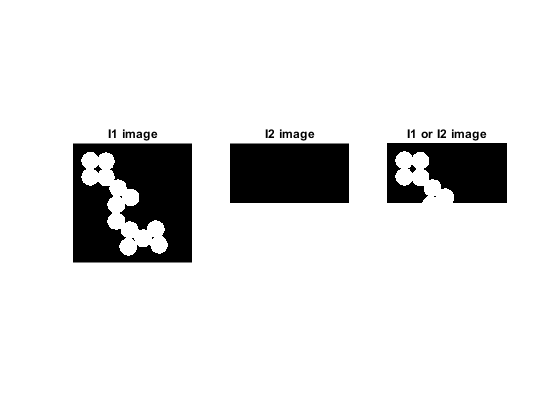

figure, subplot(1,3,1), imshow(I1), title("I1 image")
subplot(1,3,2), imshow(I2), title("I2 image")
subplot(1,3,3), imshow(or(I1,I2)), title("I1 or I2 image")

figure, subplot(1,3,1), imshow(I1), title("I1 image")
subplot(1,3,2), imshow(I2), title("I2 image")
subplot(1,3,3), imshow(I1|I2), title("I1 or I2 image")

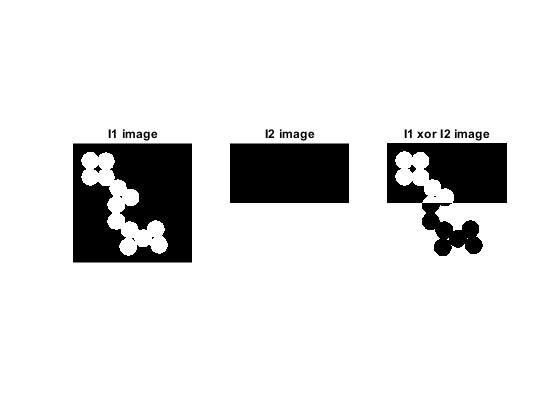

figure, subplot(1,3,1), imshow(I1), title("I1 image")
subplot(1,3,2), imshow(I2), title("I2 image")
subplot(1,3,3), imshow(xor(I1,I2)), title("I1 xor I2 image")